**surprise computation (KL)**

simple example: plot posterior p(C=cw|m), assuming Gaussian uniform noise in sensory info.

clf;
t=linspace(-5*pi,5*pi,1000);
std=0.25*pi;
T = cdf('norm',t,0,std);
figure(1);
plot(t,T);
hold on;
plot([t(1) t(end)],[0.5 0.5],'k:');
plot([0 0],[0 1],'k:');

compute 'surprise' for negative feedback ; surprise defined by KL divergence between the decision probability (expectation) and the negative feedback

the surprise of getting neg. feedback given the (avg posterior) probability of own decision

pCWgt = T;
pCCWgt = 1-T;
pnFgt = pCCWgt;
% S = pCWgt.*log2(pCWgt./pCCWgt);
S = pCWgt.*log2(pCWgt./pCCWgt) + pCCWgt.*log2(pCCWgt./pCWgt); 

% plot(t,S,'r-')
max(S)

ans = 294.1903

min(S)

ans = 7.3619e-04

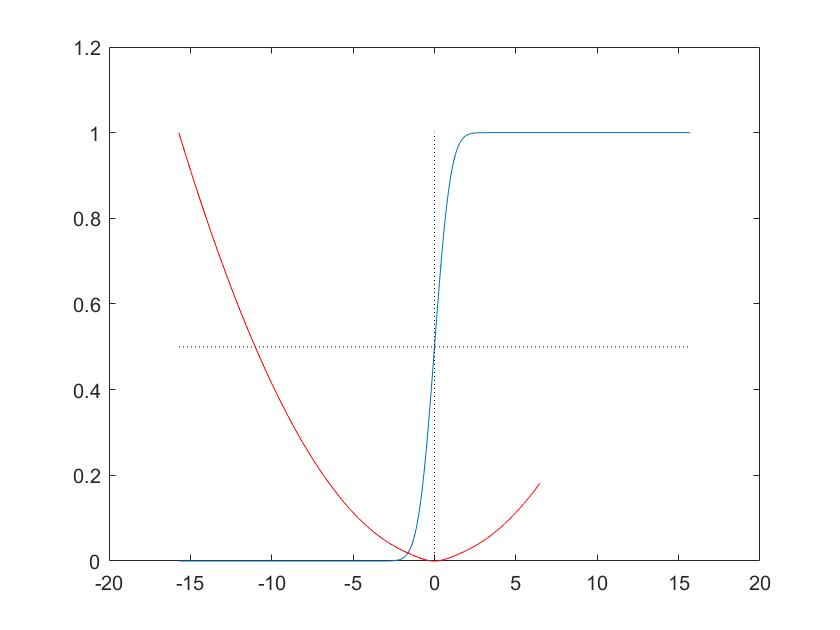

plot(t,S./(max(S)-min(S)),'r-');

S is the information gain (in bits if log2) that the observer obtained by the negative feedback (i.e. the 'surprise').

GOAL: to find a sensible way to update the likelihood function with this information gain. note this is different from traditional Bayes as there, simply flipping the prior is doing the proper exploitation of the feedback signal in terms of information. we are looking for a differently motivated strategy. such a strategy depends on the specific constraints of the system and its assumptions.

for example re-sampling: this seems like a good strategy IF the subject actually can re-sample the sensory observation from memory, i.e. instead of using the first sample (m) but acknowledgin that negative feedback is due this being one of the trials where the noise pushed m to the incorrect side, the observer has the opportunity to get a better sample!

similar (and somewhat an alternative) is using the surprise to re-weigh the strength of the sensory evidence by changing the width of the liklihood; the higher the surprise, the larger the uncertainty. 

it's not clear how such changes to the likelihood can be explained in an optimal (normative) way.